# File Name: MATLAB_Basic_04_given.m %%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear; close all;

## Create a plane point cloud.

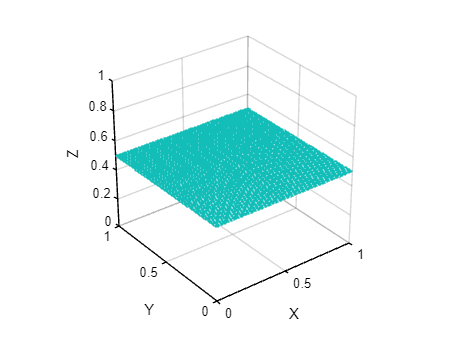

gv = 0:0.01:1;
[X,Y] = meshgrid(gv,gv);
InputPointCloud = pointCloud([X(:),Y(:),0.5*ones(numel(X),1)]);

figure

%%%%%%%%%% TODO %%%%%%%%%%
% Show point cloud.
pcshow(InputPointCloud);

xlabel('X');
ylabel('Y');
zlabel('Z');
xlim([0, 1]);
ylim([0, 1]);
zlim([0, 1]);
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], ...
    'YColor', [0. 0. 0.], ...
    'ZColor', [0. 0. 0.])

## Add uniformly distributed random noise.

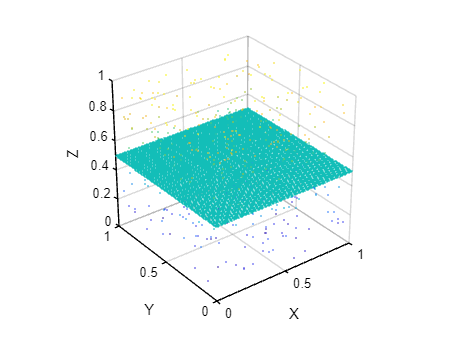

noise = rand(500, 3);

%%%%%%%%%% TODO %%%%%%%%%%
% Add random noise to point cloud.
PointCloudwithNoise = ...
    pointCloud([InputPointCloud.Location; noise]);

figure
pcshow(PointCloudwithNoise);
xlabel('X');
ylabel('Y');
zlabel('Z');
xlim([0, 1]);
ylim([0, 1]);
zlim([0, 1]);
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], ...
    'YColor', [0. 0. 0.], ...
    'ZColor', [0. 0. 0.])

## Remove outliers.

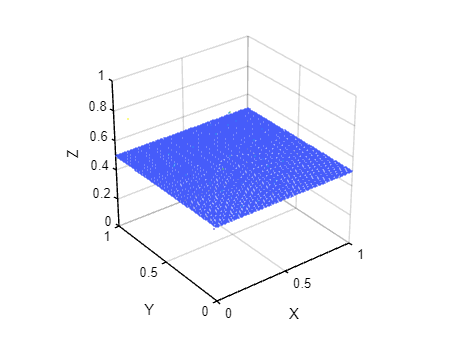

%%%%%%%%%% TODO %%%%%%%%%%
% Denoise point cloud from PointCloudwithNoise.
denoisedPointCloud = pcdenoise(PointCloudwithNoise);

figure;
pcshow(denoisedPointCloud);
xlabel('X');
ylabel('Y');
zlabel('Z');
xlim([0, 1]);
ylim([0, 1]);
zlim([0, 1]);
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], ...
    'YColor', [0. 0. 0.], ...
    'ZColor', [0. 0. 0.])